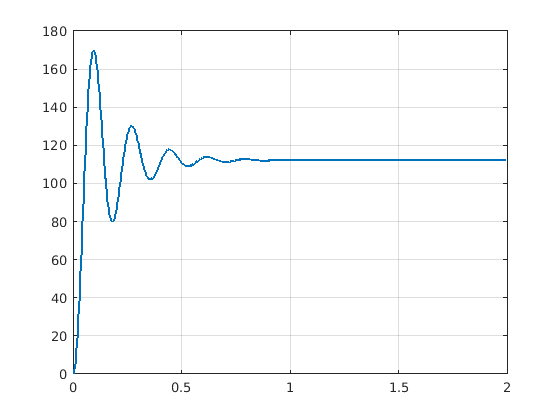

clc; clear all; close all;


Jm = 2.5*10^-4; % kg*m^2
Jeff = Jm;

Va = 12; % V
Ra = 0.4; % Ohm
La = 0.03; % H
Km = 0.1; % Nm/A

Mfr = 0.2; % Nm
omegaFr = 20; % rad/s
i_a = 0; % A
omega_m = 0; % rev/s

simTime = 2; % s
t = 0; % s
dt = 10^-5; % s
idx = 1;

while t <= simTime
    % State variables:
    % omega_m
    % i_a

    % Calculations (from Lecture 5 slide 9-10)
    M_m = Km*i_a;
    M_L = Mfr*tanh(omega_m/omegaFr);
    omega_mDot = (M_m - M_L)/Jeff;
    i_aDot = 1/La*(Va-Ra*i_a-Km*omega_m);

    % Logging
    time_plot(idx) = t;
    omega_m_plot(idx) = omega_m;

    % Time Integrate
    omega_m = omega_m + omega_mDot * dt;
    i_a = i_a + i_aDot * dt;

    % Update Variables
    t = t + dt;
    idx = idx + 1;

end

% Plotting
plot(time_plot, omega_m_plot, 'LineWidth', 2)
grid